clear all; close all; clc;

load(fullfile("Data","wavelengths.mat"));
load(fullfile("Data","variableNames.mat"));

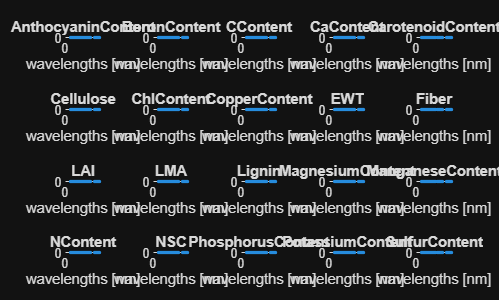

for i = 1:length(variables)
    load(fullfile("Data","splitDataset",variables(i)+".mat"));
    trait_avg(i) = mean(data(:,1));
    trait_std(i) = std(data(:,1));
    trait_size(i) = length(data(:, 1));
    trait_min(i) = min(data(:, 1));
    trait_max(i) = max(data(:, 1));
    
    avg_spectrum = mean(data(:, 2:end));
    nexttile; plot(wavelengths, avg_spectrum, '.');
    xlabel("wavelengths [nm]"); ylabel("Reflectance [a.u.]");
    title(extractBefore(variables(i), "_"));
end

headers = ["Trait", "Average", "Standard deviation", "N", "Min", "Max"]';
stat_prop = table(variables', trait_avg', trait_std', trait_size', trait_min', trait_max', 'VariableNames', headers);
mkdir(fullfile("Data","statistical_properties"))
save(fullfile("Data","statistical_properties", "stat_prop"));

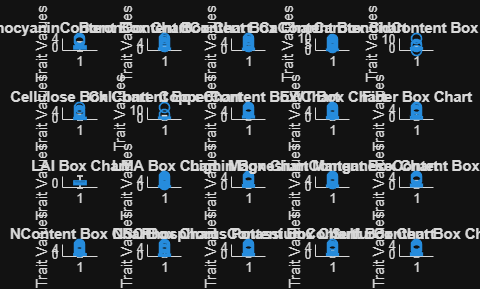

figure;
for i = 1:length(variables)
    load(fullfile("Data\splitDataset",variables(i)));
    trait = data(:,1);
    nexttile;
    boxchart(trait);
    ylabel("Trait Values");
    title(extractBefore(variables(i), "_") + " Box Chart");
end

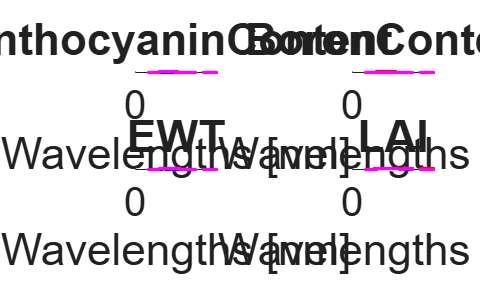

figure;
num_graphs = 5;
mm = hsv(num_graphs+1);
for i = [1, 2, 9, 11]
    load(fullfile("Data\splitDataset",variables(i)));
    data = sortrows(data, 1);
    
    nexttile; hold on;
    plot(wavelengths, data(1, 2:end), 'Color', mm(1, :), 'Marker', '.', 'LineStyle', 'none', 'LineWidth', 3);
    label = "Trait = "+num2str(data(1, 1));
    for j = 1:num_graphs-1
        idx = find(data(:, 1) >= j*data(end, 1)/num_graphs, 1);
        plot(wavelengths, data(idx, 2:end), 'Color', mm(j+1, :), 'Marker', '.', 'LineStyle', 'none', 'LineWidth', 3);
        label(j+1) = "Trait = "+num2str(data(idx, 1));
    end
    plot(wavelengths, data(end, 2:end), 'Color', mm(num_graphs+1, :), 'Marker', '.', 'LineStyle', 'none', 'LineWidth', 3);
    label(num_graphs+1) = "Trait = "+num2str(data(end, 1));
    %legend(label);
    xlabel("Wavelengths [nm]"); ylabel("Reflectance [a.u.]");
    title(extractBefore(variables(i), "_"));
    hold off;
    set(gca, 'FontSize', 24);
end